numCores = [1 2 4 8 16 32]';
v4 = [640188000, 320625000, 191978000, 128080000, 064950000, 064950000]';
S4 = v4(1)./v4;
T4 = array2table([numCores, v4], "VariableNames", {'numCores','v4',});
T4

T4 = 6×2 table
    numCores        v4    
    ________    __________

        1       6.4019e+08
        2       3.2062e+08
        4       1.9198e+08
        8       1.2808e+08
       16        6.495e+07
       32        6.495e+07



v5 = [642938001, 322617000, 177820000, 104782000, 54592000, 44812000]';
S5 = v5(1)./v5;
T5 = array2table([numCores, v5], "VariableNames", {'numCores','v5',});
T5

T5 = 6×2 table
    numCores        v5    
    ________    __________

        1       6.4294e+08
        2       3.2262e+08
        4       1.7782e+08
        8       1.0478e+08
       16       5.4592e+07
       32       4.4812e+07


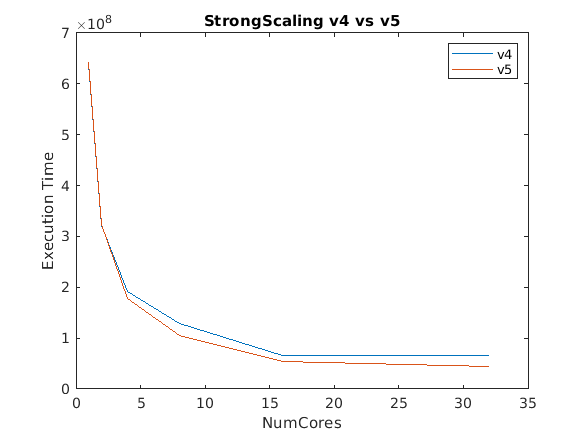


P1 = plot(numCores,[v4, v5]); title('StrongScaling v4 vs v5'); legend({'v4', 'v5'}); xlabel("NumCores"); ylabel("Execution Time");

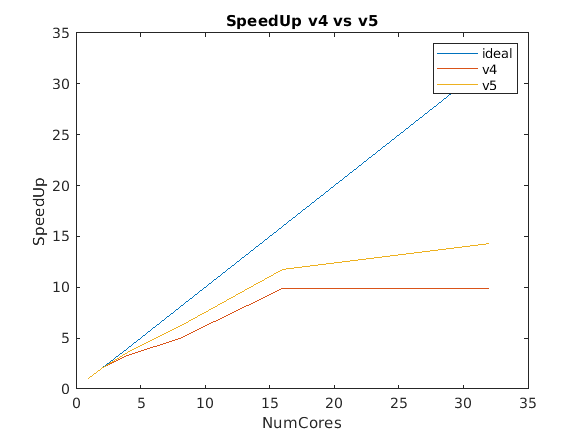

P2 = plot(numCores, [numCores,S4,S5]); title('SpeedUp v4 vs v5'); legend({'ideal', 'v4', 'v5'}); xlabel("NumCores"); ylabel("SpeedUp");